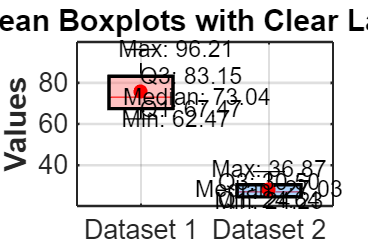

data1 = [62.47, 86.81, 79.48, 72.66, 96.21, 67.83, 73.42, 67.10];
data2 = [36.87, 27.09, 24.46, 26.97, 24.23, 27.82, 24.83, 33.19];


data = [data1(:), data2(:)];
positions = [1, 3]; 


figure('Position', [100, 100, 900, 600]); 
boxplot(data, 'Positions', positions, 'Widths', 1, 'Labels', {'Dataset 1', 'Dataset 2'}, 'Symbol', 'k+');

hold on;

h = findobj(gca, 'Tag', 'Box');
colors = [0.2 0.6 1; 1 0.4 0.4]; 
for j = 1:length(h)
    patch(get(h(j), 'XData'), get(h(j), 'YData'), colors(j, :), 'FaceAlpha', 0.4, 'EdgeColor', 'k', 'LineWidth', 2);
end


stats1 = quantile(data1, [0, 0.25, 0.5, 0.75, 1]); % Min, Q1, Median, Q3, Max
stats2 = quantile(data2, [0, 0.25, 0.5, 0.75, 1]);
mean1 = mean(data1);
mean2 = mean(data2);


plot(positions(1), mean1, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
plot(positions(2), mean2, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);


text(positions(1)+0.55, stats1(1) , sprintf('Min: %.2f', stats1(1)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.78, stats1(2), sprintf('Q1: %.2f', stats1(2)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.88, stats1(3), sprintf('Median: %.2f', stats1(3)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.78, stats1(4), sprintf('Q3: %.2f', stats1(4)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(1)+0.55, stats1(5), sprintf('Max: %.2f', stats1(5)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');


text(positions(2), stats2(1) - 1.5, sprintf('Min: %.2f', stats2(1)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(2), stats2(2) - 1.5, sprintf('Q1: %.2f', stats2(2)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(2), stats2(3) + 1.5, sprintf('Median: %.2f', stats2(3)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(2), stats2(4) + 1.5, sprintf('Q3: %.2f', stats2(4)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');
text(positions(2), stats2(5) + 1.5, sprintf('Max: %.2f', stats2(5)), 'FontSize', 14,   'Color', 'black', 'HorizontalAlignment', 'center');


set(gca, 'FontSize', 16, 'LineWidth', 1.5);
ylabel('Values', 'FontSize', 18, 'FontWeight', 'bold');
title('Clean Boxplots with Clear Labels', 'FontSize', 18, 'FontWeight', 'bold');
grid on;
hold off;


print -depsc boxplot_final.eps